# Week 3 Quiz

Use this file as a starting point for the week 3 quiz. The code to load the trained model and ground truth for the fasteners dataset is provided. You need to write code to evaluate the model and answer the questions in the Coursera quiz. Refer to the EvaluatingObjectDetectionModels.mlx file for assistance.

load ('C2-ObjectDetection\module 4\ParkingYOLOXObjectDetection.mat', 'detector')
load ('parkingTestGT.mat', 'parkingTestGT')

## Write code to evaluate the model

To complete this week's quiz you need to do the following steps:

- Run the detector on the test images with a confidence threshold of 0.05

- Evaluate the detection results using an IoU threshold of 0.5 and 0.25

- Compare the AP of all classes at both IoU thresholds

- Compare the mAP at both IoU thresholds

[imds, blds] = objectDetectorTrainingData(parkingTestGT);
testData = combine(imds, blds);

testResults = detect(detector, testData, "Threshold", 0.05)

testResults = 100×3 table
                    Boxes                        Scores            Labels      
    ______________________________________    ____________    _________________

    {[204.9172 106.8125 71.9830 108.0423]}    {[  0.9116]}    {[EV           ]}
    {3×4 single                          }    {3×1 single}    {3×1 categorical}
    {2×4 single                          }    {2×1 single}    {2×1 categorical}
    {[187.5856 89.1544 107.8222 141.4982]}    {[  0.8678]}    {[EV           ]}
    {3×4 single                          }    {3×1 single}    {3×1 categorical}
    {3×4 single                          }    {3×1 single}    {3×1 categorical}
    {[ 231.3914 123.8444 78.3436 74.5177]}    {[  0.8768]}    {[Accessible   ]}
    {2×4 single                          }    {2×1 single}    {2×1 categorical}
    {3×4 single                          }    {3×1 single}    {3×1 cate

### Out of memory errors

When passing a `datastore` to the detect function a batch of images is pulled into memory for detection. Depending on the type of detector, image size, and your available memory, this could result in an out of memory error. If that is the case, use the `"MiniBatchSize"` Name-Value pair to reduce the number of images from the default of 128. An example is shown below.

**Important**: The detector is also run in the "Choose a detection threshold" section below. Make sure to update the call to the `detect` function to specify the `MiniBatchSize` if you are getting an out of memory error.

% testResults = detect(detector, testData, "Threshold", 0.05, "MiniBatchSize", 50)

## Visualize detections

Visualizing the detections on the images helps you evaluate the model performance. Select an image to view the detections (if any) and the associated scores. 

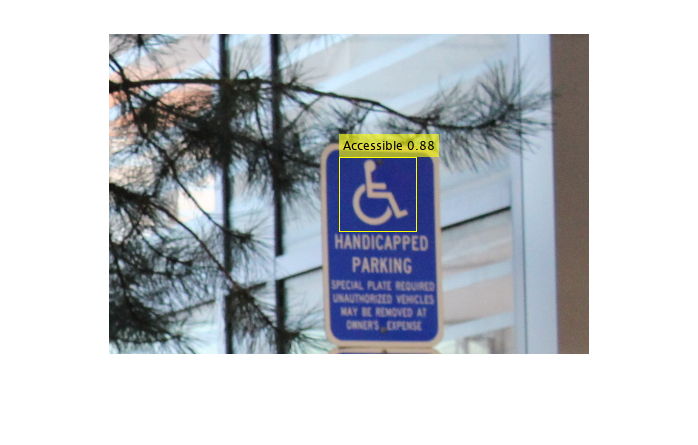

numImages = height(testResults);  % To set a limit on the control
imgIdx = 7;
img = readimage(imds, imgIdx);
label = string(testResults.Labels{imgIdx}) + " " + round(testResults.Scores{imgIdx},2);
img = insertObjectAnnotation(img, "rectangle", testResults.Boxes{imgIdx}, label);
imshow(img)

## Evaluate detection results

The `evaluateDetectionPrecision` function compares the detection results to the ground truth. The third input argument is the Intersection-over-Union (IoU) threshold used to define a true positive. The default value of 0.5 offers decent location accuracy without being too stringent and causing many false positives. However, change this value based on your application's needs. 

The function returns three outputs. The first is the average precision, AP, for each class, which tells you how well the detector performs for each class. The second and third outputs contain the recall and precision values for each class, sorted by decreasing confidence.

Run the section to evaluate the detector with the specified IoU threshold and look at the output. 

**As a bonus**, save this script with a new name, change the IoU threshold, and compare results.

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.5);
ap

ap =     0.6877
    0.9210
    1.0000


The mean of the average precision across classes, or mAP, is a useful metric for evaluating the detector as a whole. 

mAP = mean(ap)

mAP = 0.8696

% Get the list of classes from the detector
classes = detector.ClassNames;
% Evaluate the detection results
[ap2, recall, precision] = evaluateDetectionPrecision(testResults, testData, 0.25);
ap2

ap2 =     0.8242
    0.9210
    1.0000


The mean of the average precision across classes, or mAP, is a useful metric for evaluating the detector as a whole. 

mAP2 = mean(ap2)

mAP2 = 0.9151

## Visualize precision-recall curves for different classes

Visualizing the precision-recall curves for individual classes gives you more detailed information on your detector. For example, the AP can be low due to low recall, many false positives, or both. 

Use the drop-down menu to select a class and view the precision-recall curves. Compare a few letters, like A, E, C, G, O, and Y. What do the results tell you about the performance of the detector for different classes.

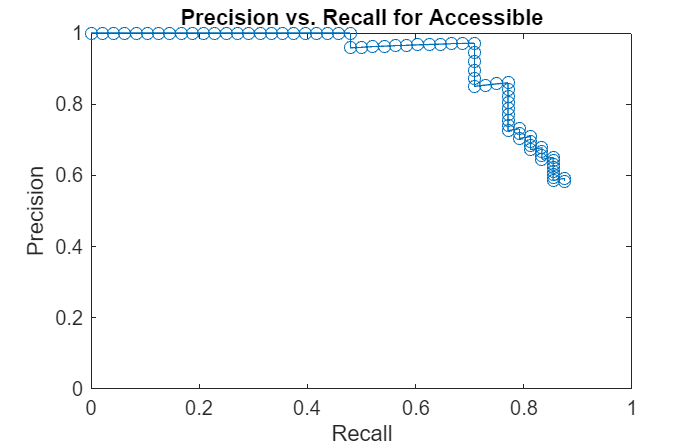

% This drop-down returns the index number for the selected class.
class = 1;
plot(recall{class}, precision{class}, "-o")
title("Precision vs. Recall for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Precision")
xlabel("Recall")

## Choose a detection threshold

An important parameter when detecting objects is the detection threshold value. Only detections with a confidence score greater than or equal to the threshold are returned by the detector. Increasing the threshold helps to limit false positives but can decrease recall as lower-confidence detections are removed. 

To find an appropriate threshold for your detector:

- Create a vector of threshold values to test 

- Run the detector with each threshold value

- Evaluate the detector to determine the AP for each class at each threshold

- Calculate the mAP for each threshold

- Plot the mAP vs. detection threshold

Run the code below to calculate mAP for a series of detection thresholds. 

**Note:** This may take a few minutes because the detector is being applied to every test image at multiple confidence thresholds.

% Vector of detection threshold values to test
thresholds = 0.05:0.05:0.9;

% Create a matrix to store the results
% Each column is the AP returned for the corresponding threshold value
apMatrix = zeros(length(classes), length(thresholds));

% Create a waitbar to monitor progress
f = waitbar(0);

% Loop through the detection thresholds, evaluate results, and save the AP
for ii = 1:length(thresholds)
    results = detect(detector, testData, "Threshold", thresholds(ii));
    apMatrix(:,ii) = evaluateDetectionPrecision(results, testData, 0.5);
    waitbar(ii/length(thresholds), f, "Running detector and evaluating results")
end
close(f)

% Calculate the mAP for each threshold
% The mean function calculates the mean of each column of the matrix
mAPList = mean(apMatrix);

## Visualize mAP vs detection threshold curve

Ideally, the curve will be relatively flat as you increase the detection threshold. This means that false positives are being suppressed without decreasing recall much. However, increasing the confidence threshold too much will reduce recall, significantly lowering the mAP. In this example, choosing a detection threshold between 0.4 to 0.5 strikes a good balance. 

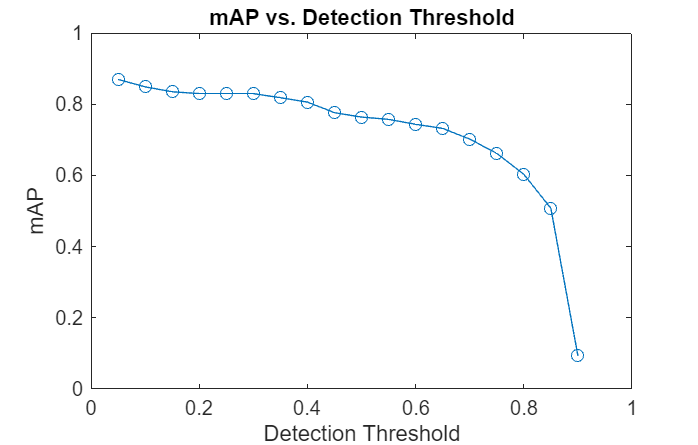

plot(thresholds, mAPList, "-o")
xlabel("Detection Threshold")
ylabel("mAP")
title("mAP vs. Detection Threshold")

## How confident is the detector for each class?

Examine the mAP plot above.

*    A decrease in mAP as detection threshold increases means true positives are lost with the higher threshold.*

But what classes are most affected by the increased detection threshold?

Plotting a row of the `apMatrix` shows how the average precision for an individual class decreases as the detection threshold increases. 

Use the drop-down menu to look at individual classes. An AP that decreases at low detection thresholds means that there are low confidence true postitives. The detector may not be very confident for that class. The letter "E" is an example with this detector.

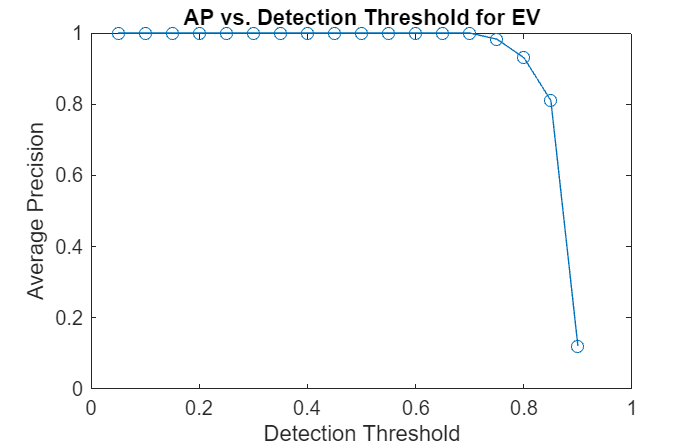

class = 3;
plot(thresholds, apMatrix(class, :), "-o")
title("AP vs. Detection Threshold for " + classes(class))
ylim([0 1])
xlim([0 1])
ylabel("Average Precision")
xlabel("Detection Threshold")

## Helper Functions

function bboxes = createBoundingBoxTable(blds)
% This helper function extracts the LabelData from a box label datastore and
% creates a table with one row for each object instead of one row for each
% image.

    % Extract the label data
    data = blds.LabelData;

    % Initialize variables to include in the table
    % ImgIdx is the index of the image in the image datastore
    % BBox is a 1x4 vector with the bounding box coordinates
    % Label is the label for the bounding box
    ImgIdx = [];
    BBox = [];
    Label = [];

    % Loop through each row in the cell array and get the bounding boxes 
    % and labels for that image.
    for ii = 1:height(data)
        currentBoxes = data{ii,1};
        currentLabels = data{ii,2};
        % Loop through the objects in the image 
        % Add the image, bounding box, and label to the corresponding variable
        for jj = 1:height(currentLabels)
            ImgIdx = [ImgIdx; ii];
            BBox = [BBox; currentBoxes(jj,:)];
            Label = [Label; currentLabels(jj)];
            
        end
    end
    % Create the output table
    bboxes = table(ImgIdx, BBox, Label);
end

function displayOutlierImage(bboxes, class, variable, outlier2view, imds)
% This help function uses the selections set by live controls to find and
% display outlier images. If the numeric selection is higher than the
% number of outliers, a message is displayed.

    % Filter the bounding boxes by class
    classTable = bboxes(bboxes.Label == class, :);
    
    % Find outlier bounding boxes based on the specified variable using quartiles
    % quartiles is used as the default for box plots and is better when
    % there are objects in the same class with different sizes.
    outlierBBoxes = find(isoutlier(classTable(:, variable), "quartiles"));
    
    % Get the indices inside the image datastore of outlier images
    outlierImages = classTable.ImgIdx(outlierBBoxes);
    
    % Calculate the number of outliers
    % This is used to check if the combination of controls is valid.
    numOutliers = length(outlierBBoxes);
    
    % Check if there are outliers and if the specified outlier2view is within range
    if ~isequal(numOutliers, 0) && outlier2view <= numOutliers
        % Get the image number of the specified outlier
        outlierImgNumber = outlierImages(outlier2view);
        
        % Get the bounding box of the specified outlier
        outlierBBox = classTable.BBox(outlierBBoxes(outlier2view), :);
        
        % Read the image corresponding to the outlier image number
        outlierImg = readimage(imds, outlierImgNumber);
        
        % Add the ground truth bounding box for the selected outlier
        annotatedImg = insertObjectAnnotation(outlierImg, "rectangle", outlierBBox, "Outlier" + class);
        
        % Display the annotated image
        imshow(annotatedImg) 
    elseif isequal(numOutliers, 0)
        % Display a message when there are no outliers for the selected combination
        disp("There are no outliers for the selected combination");
    else
        % Display a message when the specified outlier2view is out of range
        disp("There are " + numOutliers + " outliers for your selections. Choose a smaller value for outlier2view");
    end
end